clear;
load processed_thruster_data.mat
dataEst = data_sine

dataEst =

Time domain data set with 15001 samples.
Sample time: 0.002 seconds               
                                         
Outputs      Unit (if specified)         
   Force        lb                       
                                         
Inputs       Unit (if specified)         
   u1                                    
                                         


dataVal = data_square

dataVal =

Time domain data set with 7500 samples.
Sample time: 0.002 seconds              
                                        
Outputs      Unit (if specified)        
   Force        lb                      
                                        
Inputs       Unit (if specified)        
   u1                                   
                                        


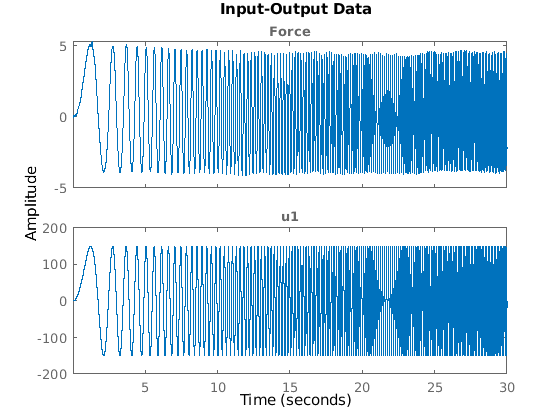



idplot(dataEst);

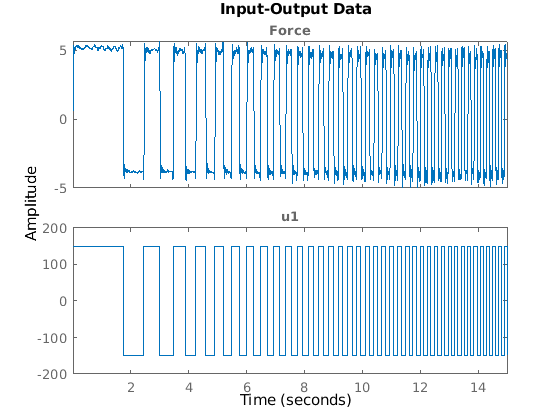

idplot(dataVal);


% using srivcstruc, first order plus zero model is good candidate!
% we want to model noise as well
nb_best = 2;
nf_best = 1;
nk_best = 2;
M_srivc = srivc(dataEst, [nb_best nf_best nk_best]);
present(M_srivc);

                                                                                                                     
M_srivc =                                                                                                            
Continuous-time OE model: y(t) = [B(s)/F(s)]u(t)                                                                     
  B(s) = 0.002706 (+/- 0.0002249) s + 3.792 (+/- 0.03717)                                                            
                                                                                                                     
  F(s) = s + 127 (+/- 1.336)                                                                                         
                                                                                                                     
Input delays (listed by channel): 0.004                                                                              
Parameterization:                                       


M = tfsrivc(dataEst, nf_best, nb_best - 1);
present(M)

                                                                                                                       
M =                                                                                                                    
                                                                                                                       
  From input "u1" to output "Force":                                                                                   
                                  0.02781 (+/- 2.561e-05) s + 0.4155 (+/- 0.01001)                                     
  exp(-(0.0109 +/- 2.67e-05)*s) * ------------------------------------------------                                     
                                               s + 13.36 (+/- 0.3375)                                                  
                                                                                                                       
Continuous-time identified transfer func

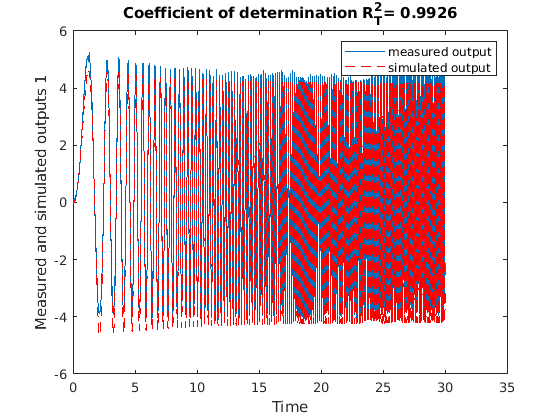

comparec(dataEst, M);

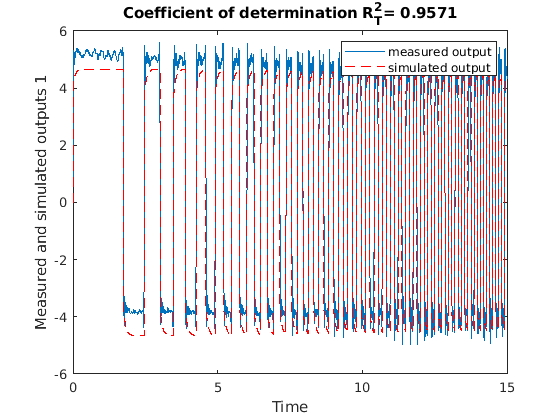

comparec(dataVal, M);

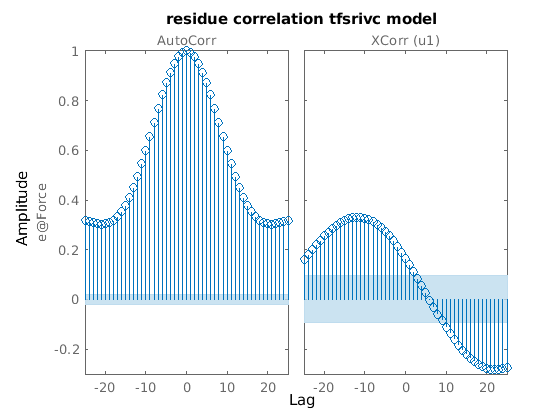

resid(dataEst, M);
title('residue correlation tfsrivc model')

Demonstration of how to use the obtained system with transformation

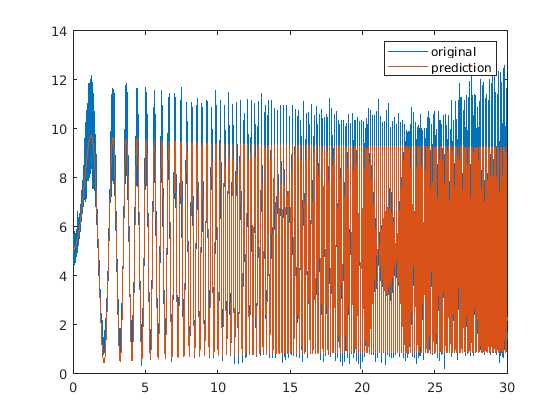

dataOriginal = load('thruster_data.mat');
transformAndPredict(dataOriginal.data_sine, time_sine, M, u_shift, y_shift)

Try to find an ARMA model for noise

% convert to form G(s) = Kp * (1+Tz*s) / (1+Tp1*s)  

sys = idproc("P1ZD");
sys.Kp = dcgain(M);
sys.Tz = M.Numerator(2) / M.Denominator(2);
sys.Tz = M.Numerator(1) / M.Numerator(2);
sys.Tp1 = 1 / M.Denominator(2);
sys.Td = M.IODelay;
% opt = procestOptions('DisturbanceModel','ARMA1');
% sysP1D = procest(dataEst,sysInit,opt)

opt = procestOptions;
opt.DisturbanceModel = 'arma1';
tempModel = procest(dataEst, 'P1ZD', opt);
% weird behaviour, high RT2 but quite offset!
% comparec(dataEst, tempModel);
% just take the noise transfer function
sys.NoiseTF = tempModel.noiseTF;
comparec(dataEst, sys);

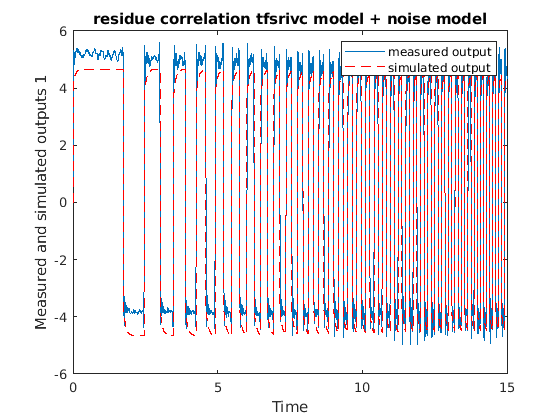

comparec(dataVal, sys);
% better than before: auto correlation generally of lower amplitude and
% more randomly, but not great
% cross correlation really low
title('residue correlation tfsrivc model + noise model')

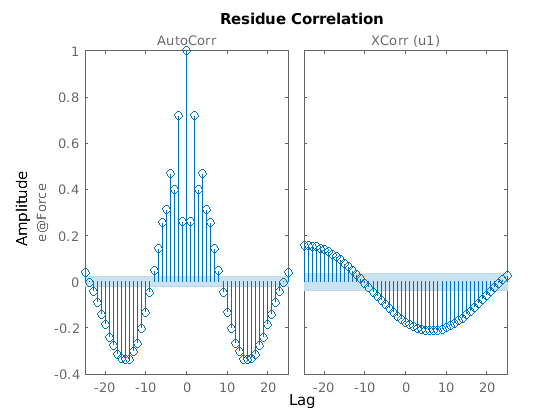

resid(dataEst, sys);

function transformAndPredict(data_original, time, tf, u_shift, y_shift)
    u_shifted = data_original.u - u_shift;
    y = lsim(tf, u_shifted, time);
    y_shifted = y + y_shift;
    plot(time, data_original.y, time, y_shifted);
    legend('original', 'prediction');
end